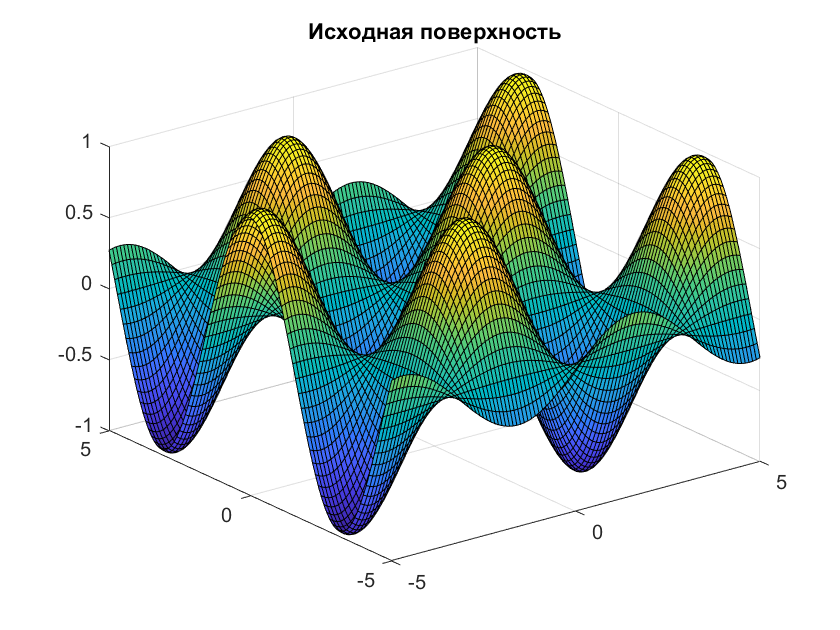

N = 5000;
X_MIN = -5;
X_MAX = 5;
Y_MIN = -5;
Y_MAX = 5;
STEP = 0.1;

dots = zeros(N,2);
z = @(X, Y) sin(X) .* cos(Y);
zx = @(X, Y) cos(X) .* cos(Y);
zy = @(X, Y) -sin(X) .* sin(Y);
dS = @(X, Y) sqrt(1 + zx(X, Y).^2 + zy(X, Y).^2);
I2 = integral2(dS, X_MIN, X_MAX, Y_MIN, Y_MAX);
f = @(X, Y) dS(X, Y)/I2;

[X,Y] = meshgrid(X_MIN:STEP:X_MAX,Y_MIN:STEP:Y_MAX);
Z = z(X, Y);
W = f(X, Y);
view(3);
surf(X,Y,Z)
title("Исходная поверхность")

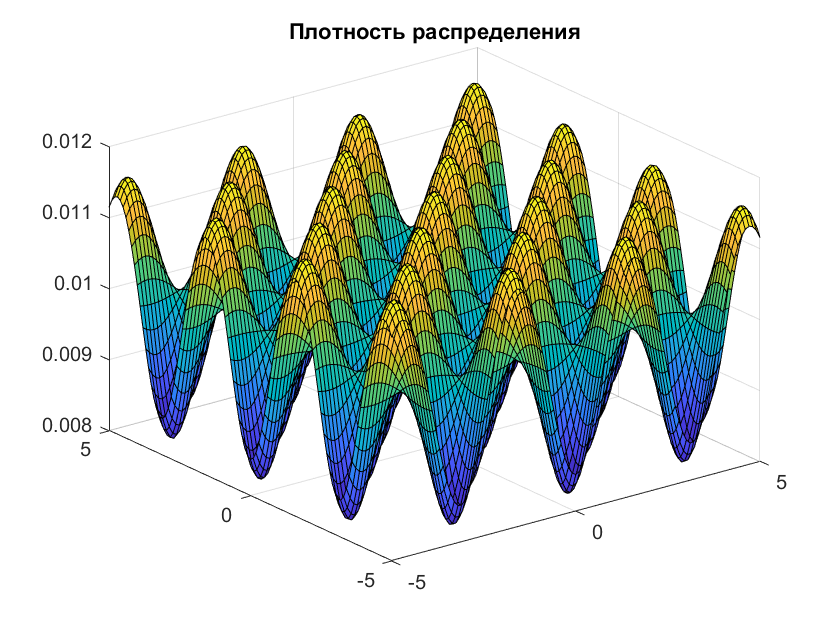

surf(X, Y, W)
title("Плотность распределения")

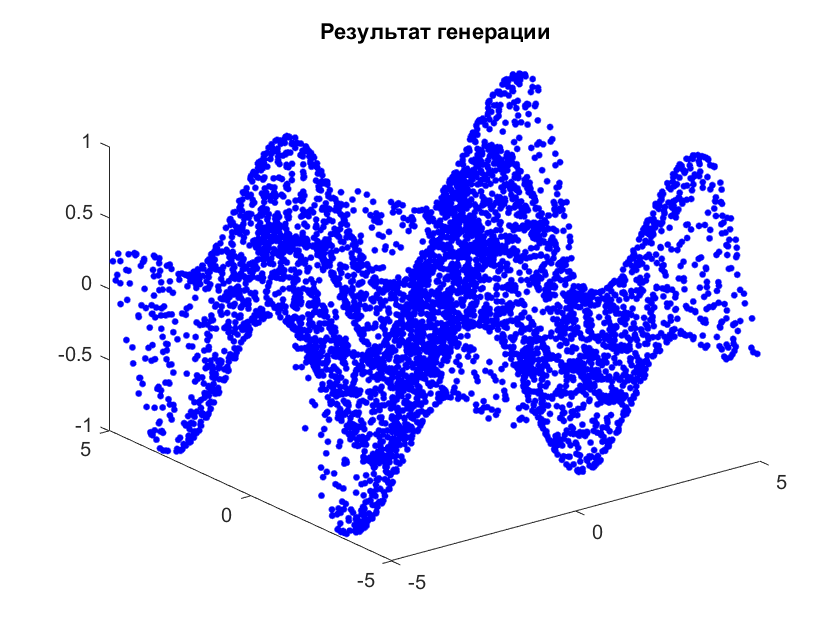


M = max(max(W));

i = 1;
while i <= N
    x0 = (X_MAX - X_MIN)*rand + X_MIN;
    y0 = (Y_MAX - Y_MIN)*rand + Y_MIN;
    if M*rand < f(x0, y0)
        dots(i,:) = [x0 y0];
        i = i + 1;
    end
end

plot3(dots(:,1), dots(:,2), z(dots(:,1), dots(:,2)), 'b.','markersize',10)
title("Результат генерации")